# 1D Stuart-Landau dynamics identification with SSMLearn

We will simulate the system 

$\dot{R} =R-R^3$,

delay embed the data and look for a 1D invariant manifold in the observable space for dimensionality reduction. We will fit a polynomial map to the evolution of the reduced coordinates. The transient nature of this problem means that DMD fails to describe the dynamics.

clearvars
close all

F = @(t,R) R-R.^3;
IC = [1e-3];

tEnd = 20;
dt = 0.04;
nSamp = tEnd/dt+1;
observable = @(x) x;

xData = integrateTrajectories(F, observable, tEnd, nSamp, 1, IC)

simulating trajectory 1 of 1...


xData = 1×2 cell array
    {1×501 double}    {1×501 double}


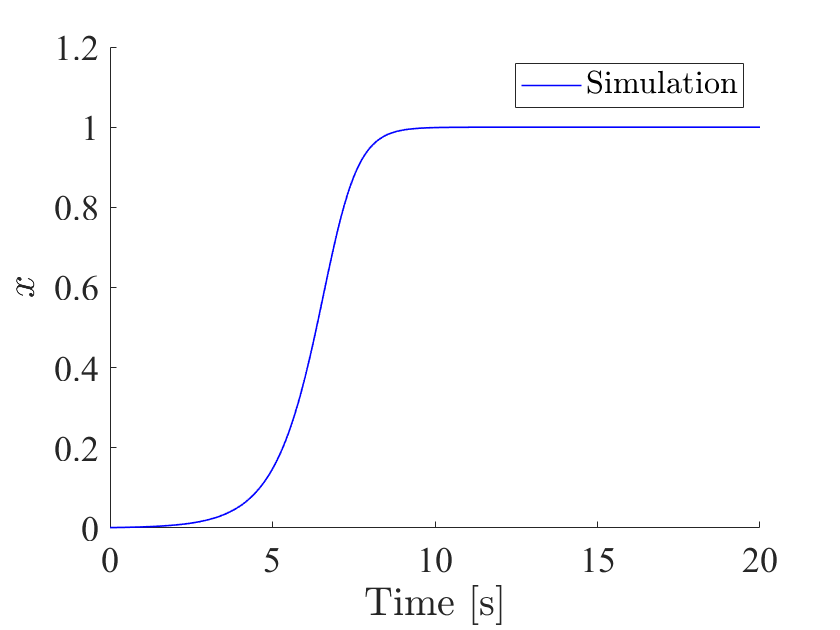

plotTrajs(xData, 'legendnames', {'Simulation'})

With delay embedding, we stack a number of subsequent snapshots of the signal to produce a higher-dimensional observable space. For a delay embedding dimension of 3, we create the vector


$$\left[\begin{array}{c} y_1(t_k)\\y_2(t_k)\\y_3(t_k) \end{array}\right]
=
\left[\begin{array}{c} x(t_k)\\x(t_k+\Delta t)\\x(t_k+2\Delta t) \end{array}\right]$$


%% Delay embedding
SSMDim = 1;
overEmbed = 0;

yData = coordinates_embedding(xData, SSMDim, 'OverEmbedding', overEmbed, 'ShiftSteps', 1)

The 3 embedding coordinates consist of the measured state and its 2 time-delayed measurements.


yData = 1×2 cell array
    {1×499 double}    {3×499 double}


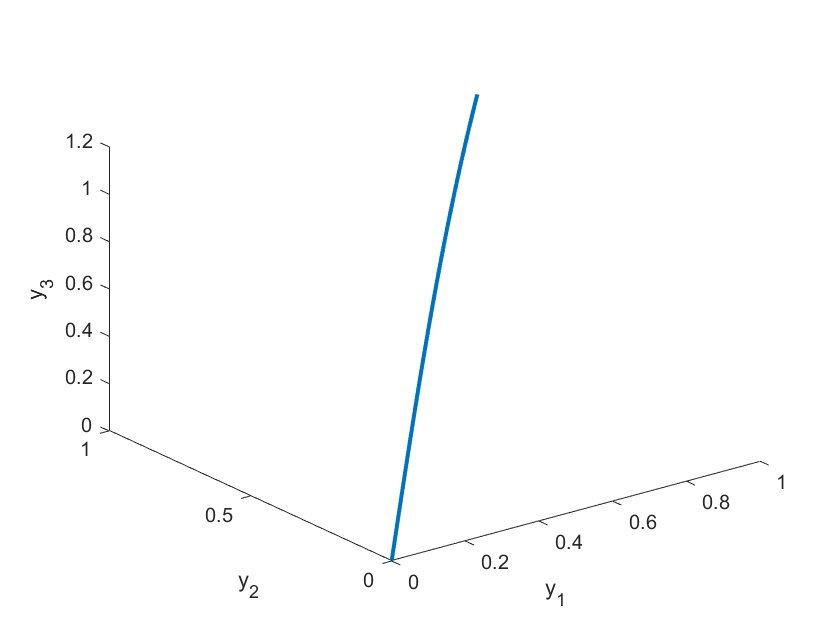

figure
plot3(yData{1,2}(1,:), yData{1,2}(2,:), yData{1,2}(3,:), 'LineWidth', 2);
xlabel('y_1'); ylabel('y_2'); zlabel('y_3'); 

%% Manifold fitting
SSMOrder = 3;
[V, SSMFunction, mfdInfo] = IMparametrization(yData, SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.044739e-06    4.441e-16    4.760e-05
    1       2    1.043201e-06    4.411e-09    1.788e-04    6.653e-05
    2       3    9.991417e-07    5.319e-07    9.985e-05    7.638e-04
    3       4    9.353414e-07    6.054e-06    1.971e-05    2.572e-03
    4       5    9.340478e-07    2.334e-09    2.590e-05    6.226e-05
    5       8    9.331690e-07    2.568e-08    2.416e-04    2.149e-04
    6       9    9.180745e-07    5.678e-08    1.327e-04    3.912e-04
    7      10    8.250933e-07    3.570e-06    8.371e-05    3.056e-03
    8      11    4.197711e-07    1.104e-04    5.111e-04    1.696e-02
    9      12    8.802966e-08    1.890e-04    4.503e-04    2.247e-02
   10      13    2.926708e-08    1.770e-05    9.345e-05    6.879e-03
   11      14    3.038428e-09    1.925e-05    4.444e-05    6.739e-03
   12      15    4.734405e-10    2.815e-06    5

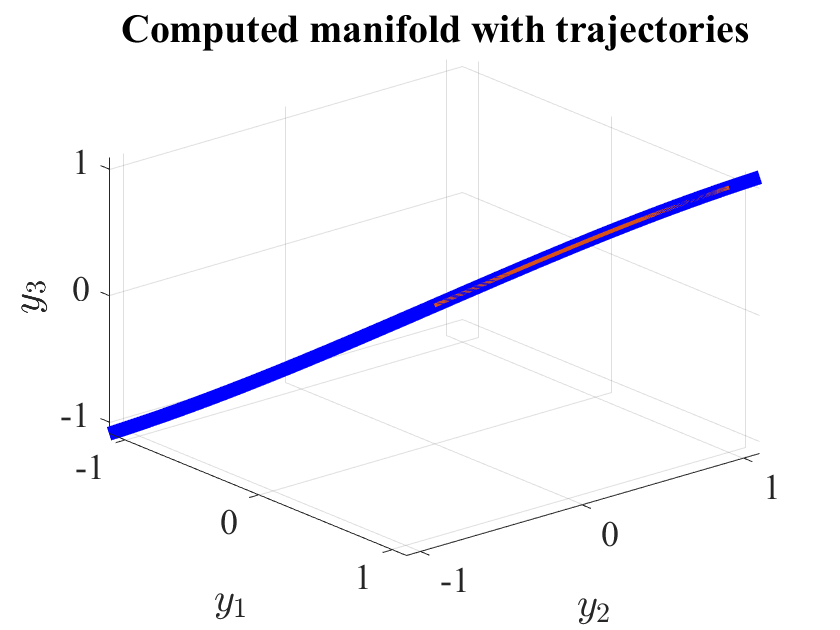


plotSSMWithTrajectories(yData, SSMFunction, [1,2,3], V, 10, 'SSMDimension', SSMDim)
view(50, 30)

Project trajectories onto the eigenspace V as:


$$\eta = V^\top y$$


etaData = getProjectedTrajs(yData, V);
RRMS = getRMS(yData, SSMFunction, V)

RRMS = 1.2036e-05

Fit a polynomial map to the estimated time derivate of the reduced coordinates


$$\eta^˙ =R\left(\eta \;\right)=a\eta +b\eta^{2\;} +c\eta^3 +\dots \;$$


%% Reduced dynamics
ROMOrder = 3;
[R,~,~,~,MapsInfo] = IMdynamics_flow(etaData, 'R_PolyOrd', ROMOrder);

Estimation of the reduced dynamics...  Done. 


disp('R coefficients')

R coefficients


disp(MapsInfo.R.coeff)

    0.9996    0.0002   -0.3335



%% Evaluation
[etaRec, yRec] = integrateFlows(R, etaData, @(eta) SSMFunction(eta));

[reducedTrajDist, fullTrajDist] = computeRecDynErrors(etaRec, yRec, etaData, yData);

RRMSE = mean(fullTrajDist)

RRMSE = 2.3489e-04

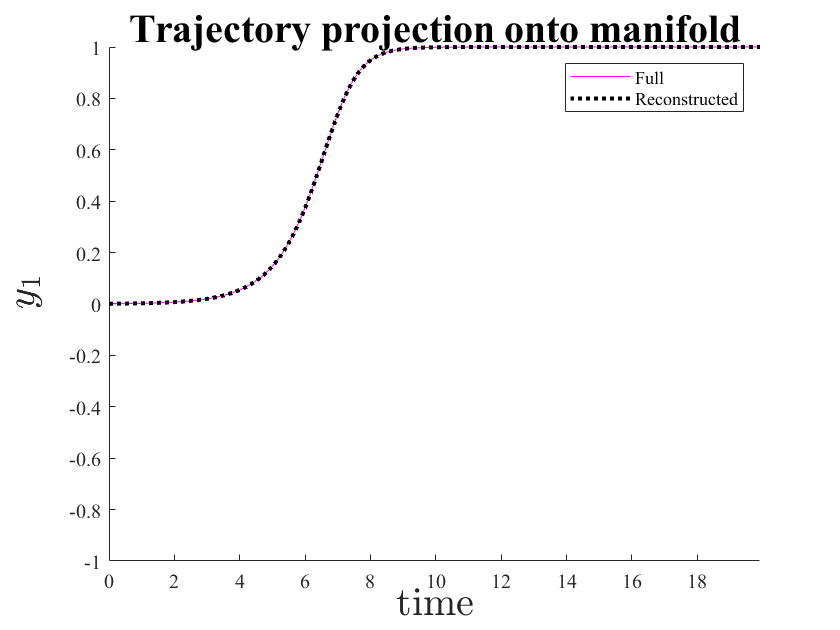


plotReconstructedTrajectory(yData, yRec, 1, 'm')

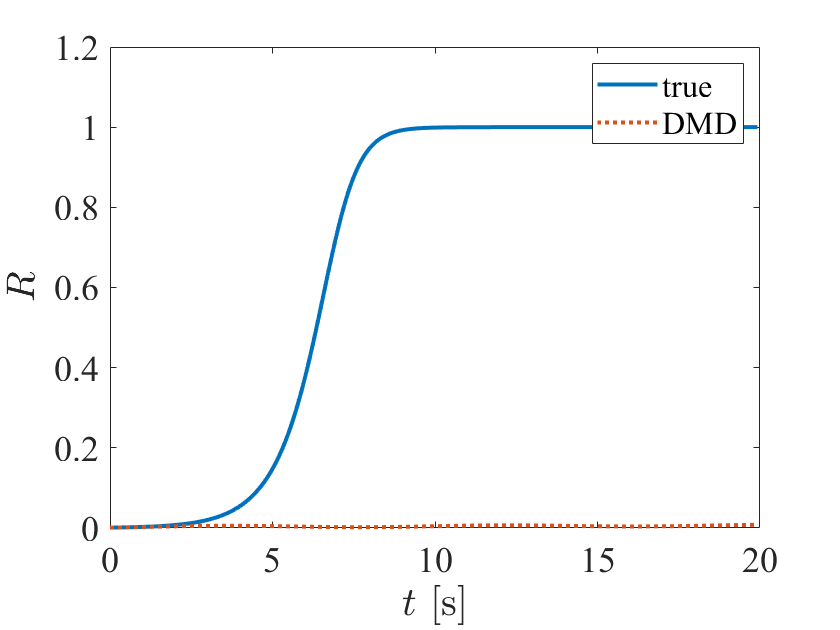

%% DMD
[Phi,omega,lambda,b,Xdmd,t] = DMD(yData{1,2}(:,1:end-1), yData{1,2}(:,2:end), 3, dt);
figure
plot(yData{1,1}, yData{1,2}(1,:), 'DisplayName', 'true', 'LineWidth', 2)
hold on
plot(t, Xdmd(1,:), ':', 'DisplayName', 'DMD', 'LineWidth', 2)
xlabel('$t$ [s]', 'Interpreter', 'latex')
ylabel('$R$', 'Interpreter', 'latex')
legend
set(gca, 'fontname', 'times')
set(gca, 'fontsize', 18)